1. Generating binary sequence and rectangular pulses

L=1000;
bs=randi([0 1],1,L);
A=1;
S=-A+(2*A).*bs;

2. Generate AWGN sequence 

u = 0;
sigma = 1;
N = u + sigma*randn(1,L);

3. Generate Recieved Signal

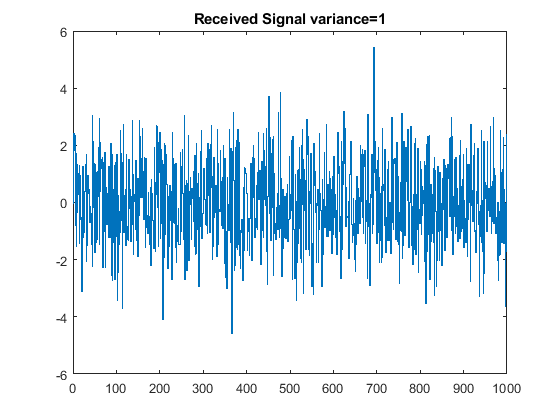

R = S + N;
stairs(R);
title("Received Signal variance=1");

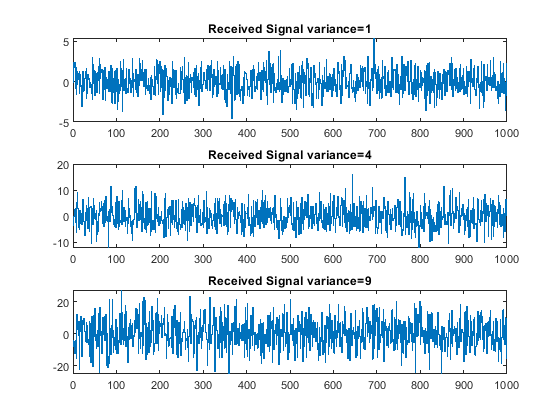


%variance=4
sigma2 = 4 ;
N2 = u + sigma2* randn(1,L);
R2 = S + N2  ; 

%variance=9
sigma3 = 9 ;
N3 = u + sigma3* randn(1,L);
R3 = S + N3 ;

%plotting the graphs
figure;
subplot(3,1,1);
stairs(R);
title("Received Signal variance=1");

subplot(3,1,2);
stairs(R2);
title("Received Signal variance=4");

subplot(3,1,3);
stairs(R3);
title("Received Signal variance=9");

It is clearly visible that when variance increases, the amplitude of the recieved signal also increases

4.  Comparison of decoded signal with transmitted signal 

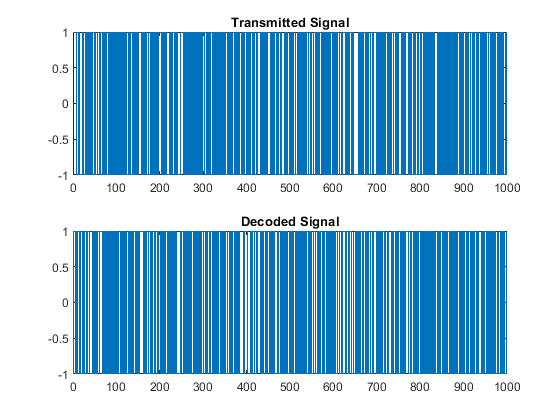

tau=0;
Y = zeros(1,L);
for j = 1:L
    if R(j) > tau
        Y(j) = A;
    else
        Y(j) = -1*A;
    end
end
figure;
subplot(2,1,1);
stairs(S);
title("Transmitted Signal");

subplot(2,1,2);
stairs(Y);
title("Decoded Signal");

It is hard to observe any differences in this scale. By zooming in x axis

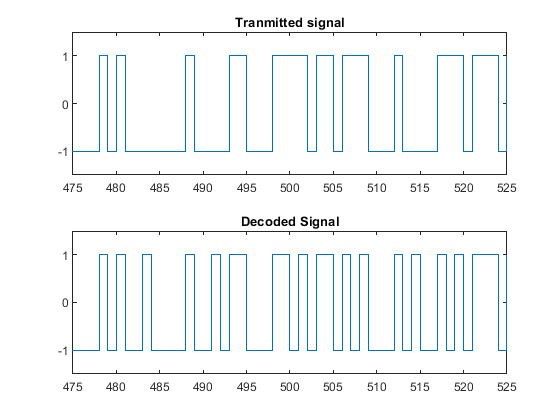

figure;
subplot(2,1,1);
stairs(S);
axis([475 525 -1.5 1.5]);
title("Tranmitted signal");

subplot(2,1,2);
stairs(Y);
axis([475 525 -1.5 1.5]);
title("Decoded Signal");

We can see that there are some error bits in the recieved signal but most of the bits are decoded correctly

5. For L=100000

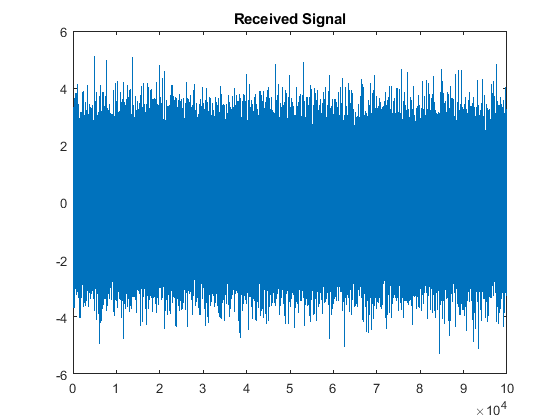

L=100000;
bs=randi([0 1],1,L);
A=1;
S=-A+(2*A).*bs;
u = 0;
sigma = 1;
N = u + sigma*randn(1,L);
R = S + N;
figure
stairs(R);
title("Received Signal");

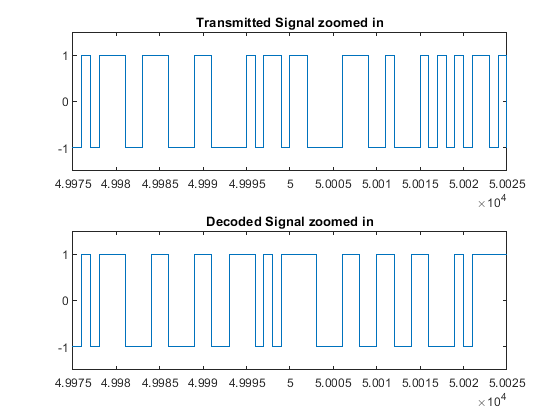

tau=0;
Y = zeros(1,L);
for j = 1:L
    if R(j) > tau
        Y(j) = A;
    else
        Y(j) = -1*A;
    end
end
figure;
subplot(2,1,1);
stairs(S);
title("Transmitted Signal zoomed in");
axis([49975 50025 -1.5 1.5]);
subplot(2,1,2);
stairs(Y);
axis([49975 50025 -1.5 1.5]);
title("Decoded Signal zoomed in");

Histogram

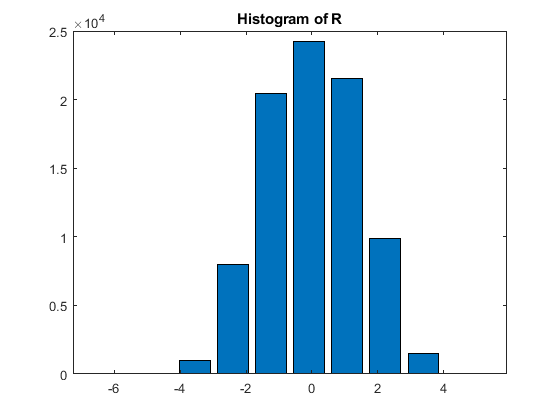

bins=10;
h=(max(R)-min(R))/(bins-1);
cls=min(R)-h/2:h:max(R); 
tally=zeros(1,bins);
for l=1:L
    for n=1:bins
        if (R(l)>=cls(n)-h/2)&&(R(l)<cls(n)+h/2)
            tally(n)=tally(n)+1;
        end
    end
end
tally=tally/h;
figure
bar(cls,tally)
title("Histogram of R");

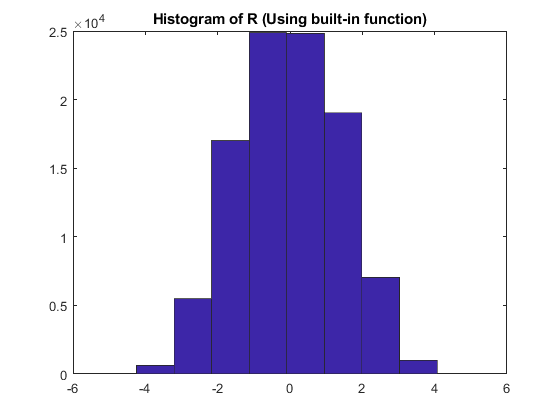


figure;
hist(R,bins);
title("Histogram of R (Using built-in function)");

5)a. For bins=100

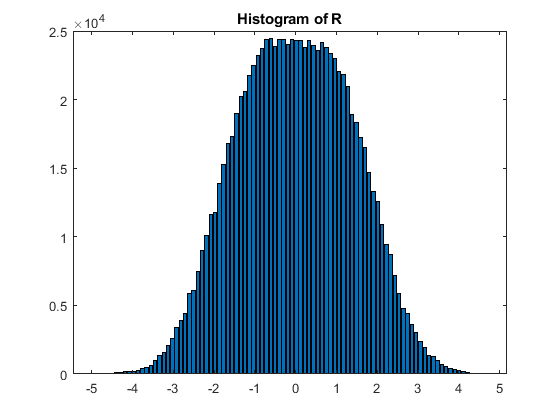

bins=100;
h=(max(R)-min(R))/(bins-1);
cls=min(R)-h/2:h:max(R); 
tally=zeros(1,bins);
for l=1:L
    for n=1:bins
        if (R(l)>=cls(n)-h/2)&&(R(l)<cls(n)+h/2)
            tally(n)=tally(n)+1;
        end
    end
end
tally=tally/h;
figure
bar(cls,tally)
title("Histogram of R");

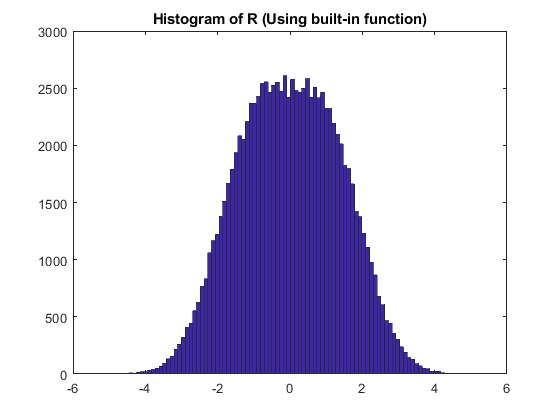


figure;
hist(R,bins);
title("Histogram of R (Using built-in function)");

5)b. PDF of f_R|S(r|S=A)

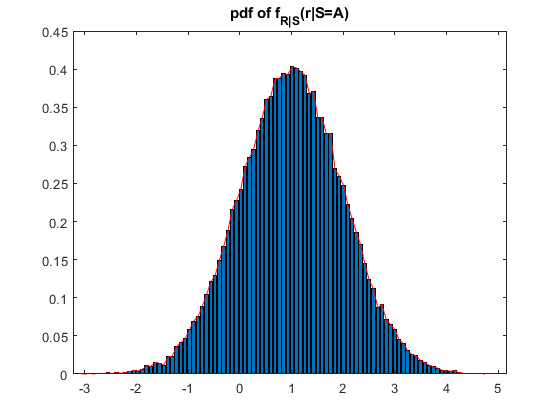

rsa=[];
rsb=[];
for l=1:L
    if S(l)==A
        rsa(end+1)=R(l);
    else
        rsb(end+1)=R(l);
    end
end

bin1=100;
h1=(max(rsa)-min(rsa))/(bin1-1);
cls1=min(rsa)-h1/2:h1:max(rsa);
figure;
[y1,x1] = hist(rsa,cls1);
y1 = y1/((length(rsa)-1)*h1);
figure;
bar(x1,y1);
hold on;
plot(x1,y1,'r');
title("pdf of f_{R|S}(r|S=-A)");
title("pdf of f_{R|S}(r|S=A)");

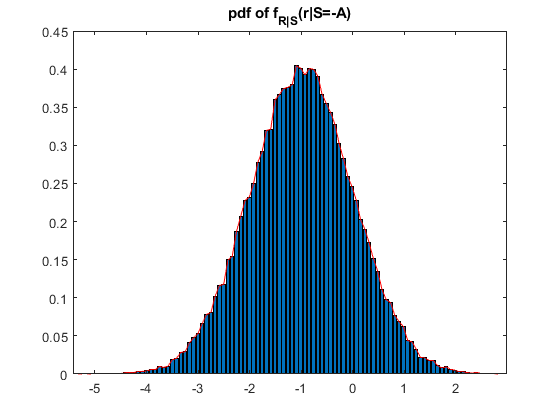


bin2=100;
h2=(max(rsb)-min(rsb))/(bin2-1);
cls2=min(rsb)-h2/2:h2:max(rsb);
figure;
[y2,x2] = hist(rsb,cls2);
y2 = y2/((length(rsb)-1)*h2);
figure;
bar(x2,y2);
hold on;
plot(x2,y2,'r');
title("pdf of f_{R|S}(r|S=-A)");


ER_SA=sum(h1.*x1.*y1)

ER_SA = 1.0013

ER_SB=sum(h2.*x2.*y2)

ER_SB = -0.9950

[y,x]=hist(R,cls);
y=y/(L*h);
ER=sum(h.*x.*y)

ER = -0.0022

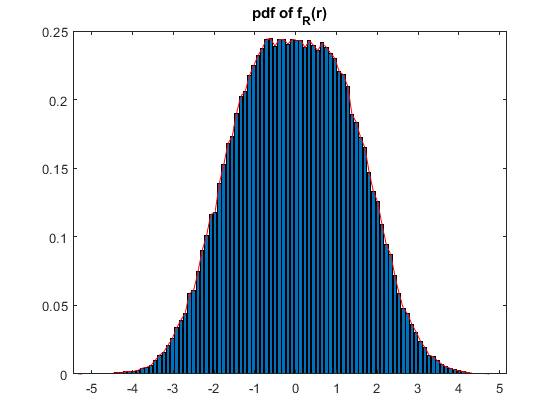

figure;
bar(x,y);
hold on;
plot(x,y,'r');
title("pdf of f_R(r)");

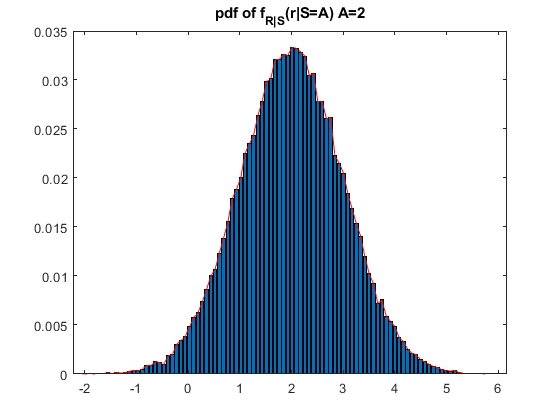

A=2;
S=-A+(2*A).*bs;

R = S + N;
rsa=[];
rsb=[];
for l=1:L
    if S(l)==A
        rsa(end+1)=R(l);
    else
        rsb(end+1)=R(l);
    end
end

bin1=100;
h1=(max(rsa)-min(rsa))/(bin1-1);
cls1=min(rsa)-h1/2:h1:max(rsa);
figure;
[y1,x1] = hist(rsa,cls1);
y1 = y1/((length(rsa)-1));
figure;
bar(x1,y1);
hold on;
plot(x1,y1,'r');
title("pdf of f_{R|S}(r|S=A) A=2");

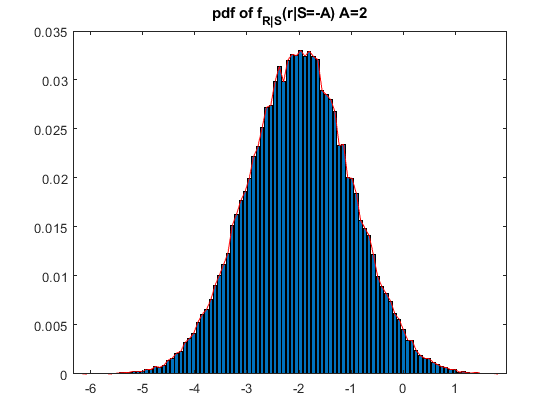


bin2=100;
h2=(max(rsb)-min(rsb))/(bin2-1);
cls2=min(rsb)-h2/2:h2:max(rsb);
figure;
[y2,x2] = hist(rsb,bin2);
y2 = y2/((length(rsb)-1));
figure;
bar(x2,y2);
hold on;
plot(x2,y2,'r');
title("pdf of f_{R|S}(r|S=-A) A=2");

ER_SA=sum(h1.*x1.*y1)

ER_SA = 0.1656

ER_SB=sum(h2.*x2.*y2)

ER_SB = -0.1657


h=(max(R)-min(R))/(bins-1);
cls=min(R)-h/2:h:max(R);
[y,x]=hist(R,cls);
y=y/(L*h);
ER=sum(h.*x.*y)

ER = -0.0074

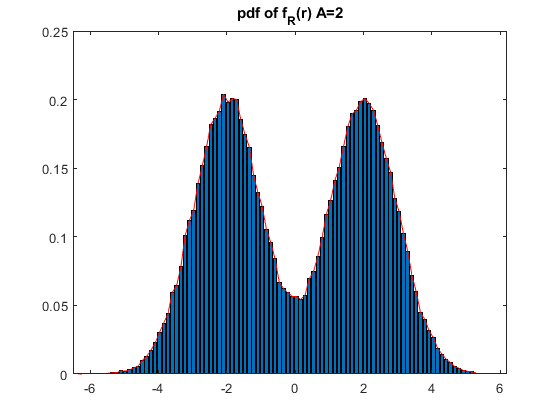

figure;
bar(x,y);
hold on;
plot(x,y,'r');
title("pdf of f_R(r) A=2");

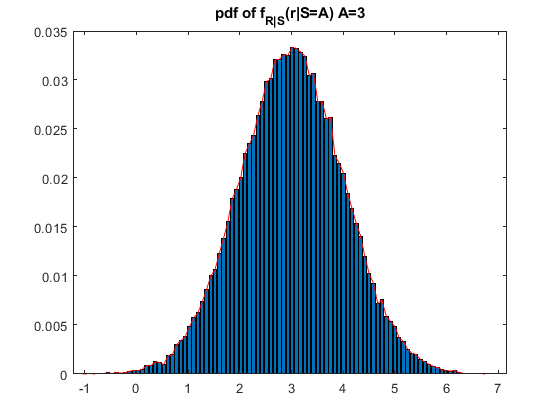

A=3;
S=-A+(2*A).*bs;

R = S + N;
rsa=[];
rsb=[];
for l=1:L
    if S(l)==A
        rsa(end+1)=R(l);
    else
        rsb(end+1)=R(l);
    end
end

bin1=100;
h1=(max(rsa)-min(rsa))/(bin1-1);
cls1=min(rsa)-h1/2:h1:max(rsa);
figure;
[y1,x1] = hist(rsa,cls1);
y1 = y1/((length(rsa)-1));
figure;
bar(x1,y1);
hold on;
plot(x1,y1,'r');
title("pdf of f_{R|S}(r|S=A) A=3");

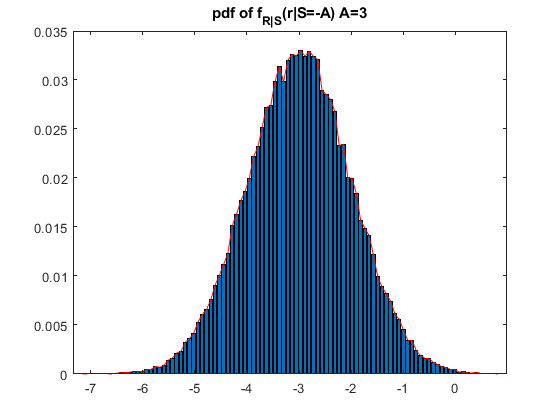


bin2=100;
h2=(max(rsb)-min(rsb))/(bin2-1);
cls2=min(rsb)-h2/2:h2:max(rsb);
figure;
[y2,x2] = hist(rsb,bin2);
y2 = y2/((length(rsb)-1));
figure;
bar(x2,y2);
hold on;
plot(x2,y2,'r');
title("pdf of f_{R|S}(r|S=-A) A=3");

ER_SA=sum(h1.*x1.*y1)

ER_SA = 0.2483

ER_SB=sum(h2.*x2.*y2)

ER_SB = -0.2487


h=(max(R)-min(R))/(bins-1);
cls=min(R)-h/2:h:max(R);
[y,x]=hist(R,cls);
y=y/(L*h);
ER=sum(h.*x.*y)

ER = -0.0129

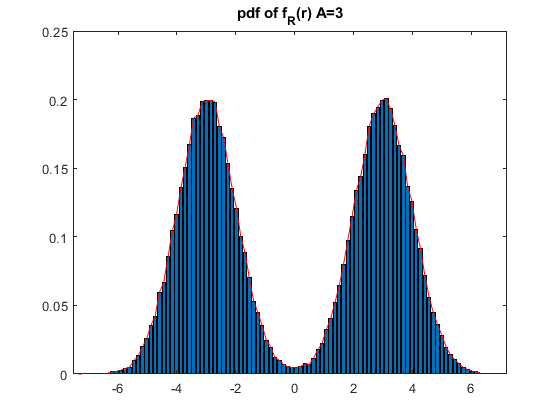

figure;
bar(x,y);
hold on;
plot(x,y,'r');
title("pdf of f_R(r) A=3");

6. Effect of inteference

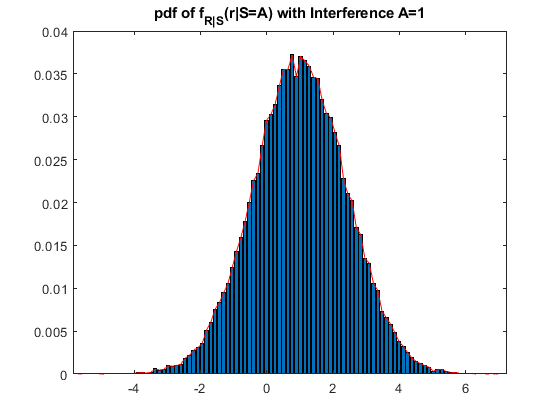

u_i = 0;
sigma = 1;
I = u_i + sigma*randn(1,L);

A=1;
S=-A+(2*A).*bs;

R = S + N + I;
rsa=[];
rsb=[];
for l=1:L
    if S(l)==A
        rsa(end+1)=R(l);
    else
        rsb(end+1)=R(l);
    end
end

bin1=100;
h1=(max(rsa)-min(rsa))/(bin1-1);
cls1=min(rsa)-h1/2:h1:max(rsa);
figure;
[y1,x1] = hist(rsa,cls1);
y1 = y1/((length(rsa)-1));
figure;
bar(x1,y1);
hold on;
plot(x1,y1,'r');
title("pdf of f_{R|S}(r|S=A) with Interference A=1");

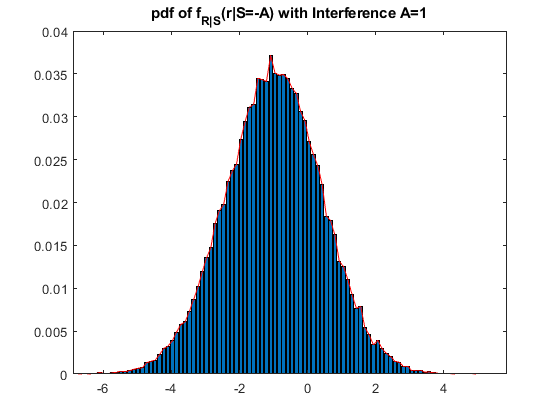


bin2=100;
h2=(max(rsb)-min(rsb))/(bin2-1);
cls2=min(rsb)-h2/2:h2:max(rsb);
figure;
[y2,x2] = hist(rsb,bin2);
y2 = y2/((length(rsb)-1));
figure;
bar(x2,y2);
hold on;
plot(x2,y2,'r');
title("pdf of f_{R|S}(r|S=-A) with Interference A=1");


ER_SA=sum(h1.*x1.*y1)

ER_SA = 0.1292

ER_SB=sum(h2.*x2.*y2)

ER_SB = -0.1258


h=(max(R)-min(R))/(bins-1);
cls=min(R)-h/2:h:max(R);
[y,x]=hist(R,cls);
y=y/(L*h);
ER=sum(h.*x.*y)

ER = 1.6886e-04

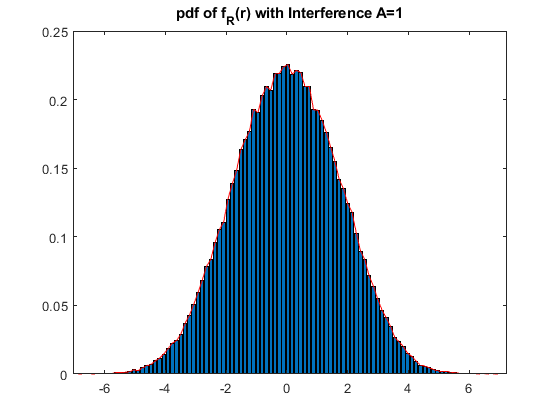

figure;
bar(x,y);
hold on;
plot(x,y,'r');
title("pdf of f_R(r) with Interference A=1");

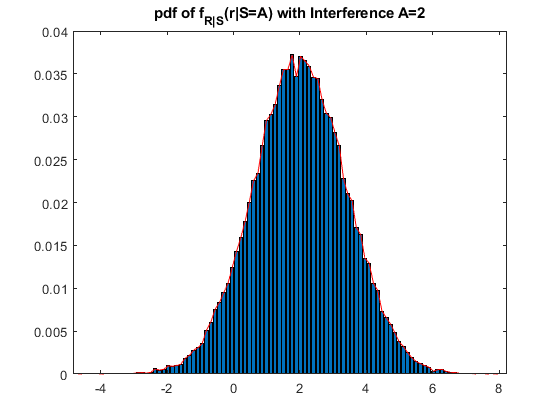

A=2;
S=-A+(2*A).*bs;

R = S + N + I;
rsa=[];
rsb=[];
for l=1:L
    if S(l)==A
        rsa(end+1)=R(l);
    else
        rsb(end+1)=R(l);
    end
end

bin1=100;
h1=(max(rsa)-min(rsa))/(bin1-1);
cls1=min(rsa)-h1/2:h1:max(rsa);
figure;
[y1,x1] = hist(rsa,cls1);
y1 = y1/((length(rsa)-1));
figure;
bar(x1,y1);
hold on;
plot(x1,y1,'r');
title("pdf of f_{R|S}(r|S=A) with Interference A=2");

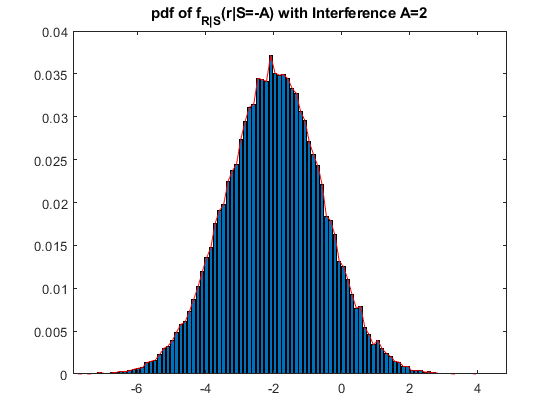


bin2=100;
h2=(max(rsb)-min(rsb))/(bin2-1);
cls2=min(rsb)-h2/2:h2:max(rsb);
figure;
[y2,x2] = hist(rsb,bin2);
y2 = y2/((length(rsb)-1));
figure;
bar(x2,y2);
hold on;
plot(x2,y2,'r');
title("pdf of f_{R|S}(r|S=-A) with Interference A=2");


ER_SA=sum(h1.*x1.*y1)

ER_SA = 0.2582

ER_SB=sum(h2.*x2.*y2)

ER_SB = -0.2527


h=(max(R)-min(R))/(bins-1);
cls=min(R)-h/2:h:max(R);
[y,x]=hist(R,cls);
y=y/(L*h);
ER=sum(h.*x.*y)

ER = -0.0052

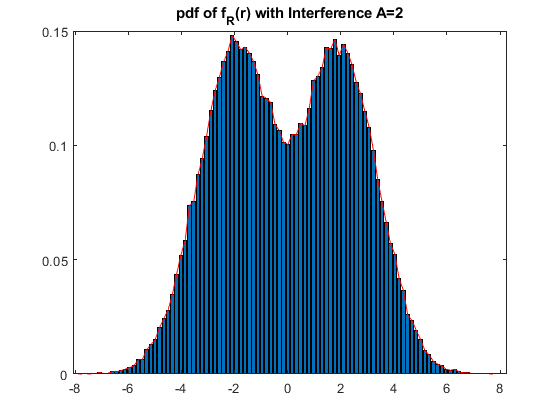

figure;
bar(x,y);
hold on;
plot(x,y,'r');
title("pdf of f_R(r) with Interference A=2");

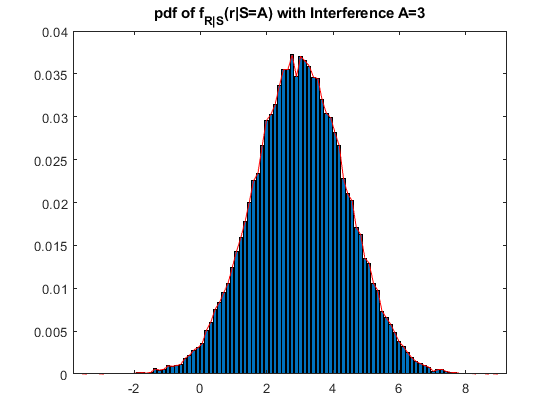

A=3;
S=-A+(2*A).*bs;

R = S + N + I;
rsa=[];
rsb=[];
for l=1:L
    if S(l)==A
        rsa(end+1)=R(l);
    else
        rsb(end+1)=R(l);
    end
end

bin1=100;
h1=(max(rsa)-min(rsa))/(bin1-1);
cls1=min(rsa)-h1/2:h1:max(rsa);
figure;
[y1,x1] = hist(rsa,cls1);
y1 = y1/((length(rsa)-1));
figure;
bar(x1,y1);
hold on;
plot(x1,y1,'r');
title("pdf of f_{R|S}(r|S=A) with Interference A=3");

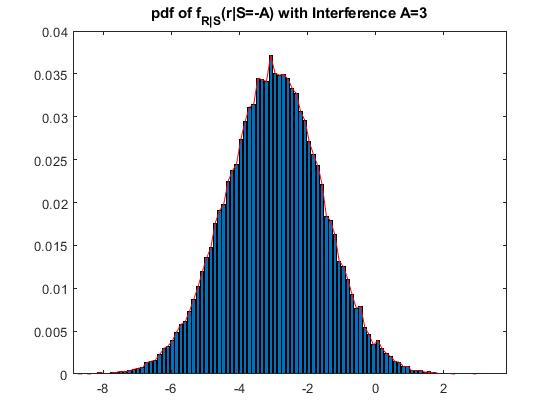


bin2=100;
h2=(max(rsb)-min(rsb))/(bin2-1);
cls2=min(rsb)-h2/2:h2:max(rsb);
figure;
[y2,x2] = hist(rsb,bin2);
y2 = y2/((length(rsb)-1));
figure;
bar(x2,y2);
hold on;
plot(x2,y2,'r');
title("pdf of f_{R|S}(r|S=-A) with Interference A=3");


ER_SA=sum(h1.*x1.*y1)

ER_SA = 0.3872

ER_SB=sum(h2.*x2.*y2)

ER_SB = -0.3797


h=(max(R)-min(R))/(bins-1);
cls=min(R)-h/2:h:max(R);
[y,x]=hist(R,cls);
y=y/(L*h);
ER=sum(h.*x.*y)

ER = -0.0101

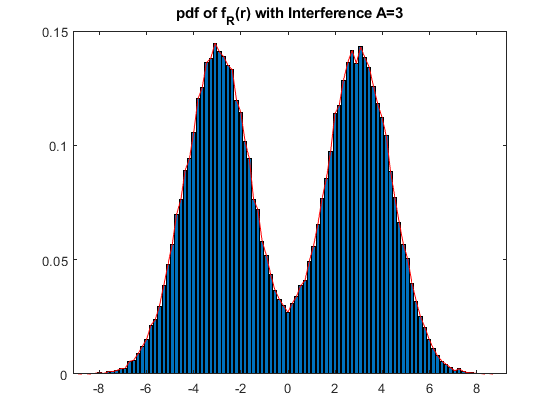

figure;
bar(x,y);
hold on;
plot(x,y,'r');
title("pdf of f_R(r) with Interference A=3");